### Experimentally measure how the MQC ratio $I_2 /I_{\;0}$ relies on the average pulse interval $\tau \;$, and flip angle error

clc;clear

L=8;

load Exp_F(phi,t).mat
load Exp_STD_F(phi,t).mat

[Ratio,Ratio_std]=CalculateRatio(S,L,std_S);

save('Exp_plw1=108wto117w_xi=-0.1_-0.1_0.2_ns=4_tauTimesLoop=200_Ratio.mat','Ratio')
save('Exp_plw1=108wto117w_xi=-0.1_-0.1_0.2_ns=4_tauTimesLoop=200_Ratio_std.mat','Ratio_std')

tau=2.4:0.2:6; %in us
x=tau;
plw1=roundn(113*(0.98:0.01:1.02).^2,-2)

plw1 =   108.5300  110.7500  113.0000  115.2700  117.5700


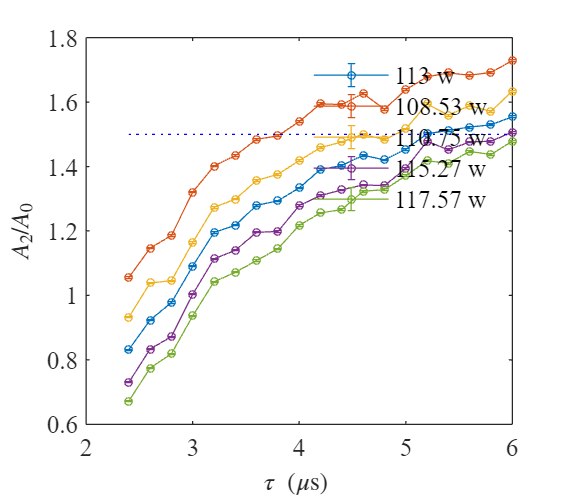

figure()
for i=1:5
error_bar=1.96*Ratio_std((i-1)*length(tau)+1:i*length(tau));
errorbar(x,Ratio((i-1)*length(tau)+1:i*length(tau)),error_bar,'-o','MarkerSize',3,'CapSize',3)
hold on
end
plot([x(1),x(end)],[1.5,1.5],'b:')
xlabel('$\tau\ (\mathrm{\mu s})$ ','Interpreter','latex')
ylabel('$A_2/A_0$','Interpreter','latex')
legend('113 w','108.53 w','110.75 w','115.27 w','117.57 w','box','off')

% xlim([4 6])
% ylim([1.3 1.6])
fontsize(gcf,10,'points')
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,8,7]);

function [S,std_S,td1]=process_FID(expdir,ExpNum_seq)

ii=1;

y0=cell(1,length(ExpNum_seq));
for Expno=ExpNum_seq
    specstruc = getspec2D([expdir,'\',num2str(Expno)]);
    y0{ii}=specstruc;
    ii=ii+1;
end

for Expno=1:length(y0)
    figure()

    y1=y0{Expno};

    sw=y1.swh(1,2); %spectral width, in Hz
    SamplingInterval=1/sw; %Sampling point interval, in s
    td2=y1.td(1,2); %number of points on direct dimension dim2
    td1=y1.td(1,1); %number of points on indirect dimension dim1

    AqTime=SamplingInterval*(td2/2-1); %sampling time, in s

    t=0:SamplingInterval:AqTime;
    RealFid=real(y1.fid);
    ImagFid=-imag(y1.fid);

    Plot Both the imaginary and real parts of FID

    %         figure()
    %         plot(t,RealFid)
    %         xlabel('Free induction time (s)')
    % %         xlim([0.5 3]*1e-4)
    %         ylabel('Real signal')
    %         figure()
    %         plot(t,ImagFid)
    %         xlabel('Free induction time (s)')
    %         ylabel('Imag signal')

    [value loc1]=max(abs(RealFid(1,:)));
    %         loc1=122;
    Observable(Expno,1:td1)=RealFid(:,loc1);

    NoiseSampling=100;

    % figure()
    % plot(t(end-NoiseSampling:end),RealFid(1,end-NoiseSampling:end))
    % xlabel('Free induction time (s)')
    % ylabel('FID')

    [noise1,mean1]=var(RealFid(:,end-NoiseSampling:end),0,2);
    noise(Expno,1:td1)=noise1.^0.5;

    S=Observable;

    norm=46086;
    S=S/norm;
    std_S=mean(noise,'all')/norm;
end
end

function [Ratio,Ratio_std]=CalculateRatio(S,L,std_S)

RealPart=real(fftshift(fft(S,L,2)/L,2));

ZeroOrder=RealPart(:,L/2+1);
DoubleOrder=RealPart(:,L/2+1-2);

Ratio=(DoubleOrder./ZeroOrder)';
var_Double=std_S^2/2/L;
var_Zero=std_S^2/L;
Ratio_std=sqrt(var_Double./(ZeroOrder.^2)+var_Zero*(DoubleOrder.^2)./(ZeroOrder.^4));  %ref: https://www.pianshen.com/article/71539931/
end
